A = [0 1; 0 0];
B = [0; Brudder(2)];
C = [1 0];
D = [0];


Aw = [0 C; zeros([2,1]) A];
Bw = [D; B];
Cw = eye(3);
Dw = [0;0;0];

sysw = ss(Aw,Bw,Cw,Dw);
Q = diag([10, 0, 1]);
R = [1];
Kthrust = lqr(sysw,Q,R)

Kthrust =     3.1623    7.0115    7.7730


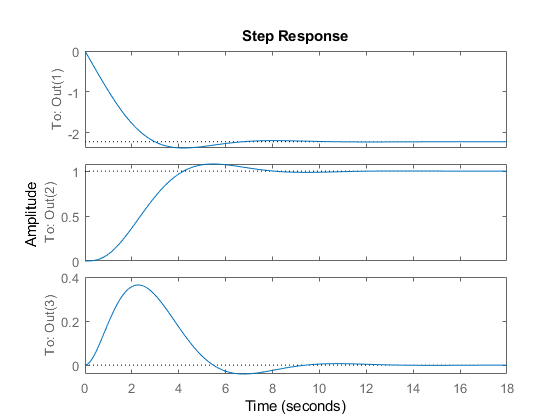


Acl = Aw-Bw*Kthrust;
Bcl = [-1; 0; 0];
Ccl = eye(3);
Dcl = [0;0;0];

syscl = ss(Acl,Bcl,Ccl,Dcl);

step(syscl)


A = [   0, 9.8, 0;
        0,   0,  1;
        0,   0,  0];
B = [0; 0; 1];
C = [1 0 0];
D = zeros([1,1]);

Aw = [0 C;
      zeros([3,1]) A];

Aw =          0    1.0000         0         0
         0         0    9.8000         0
         0         0         0    1.0000
         0         0         0         0


Bw = [D; B];

Bw =      0
     0
     0
     1


Cw = eye(4);

Cw =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Dw = zeros([4,1]);

Dw =      0
     0
     0
     0



sysw = ss(Aw,Bw,Cw,Dw);

sysw =
 
  A = 
        x1   x2   x3   x4
   x1    0    1    0    0
   x2    0    0  9.8    0
   x3    0    0    0    1
   x4    0    0    0    0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



Q = diag([10, 0, 1, 1]);

Q =     10     0     0     0
     0     0     0     0
     0     0     1     0
     0     0     0     1


R = [1];

R = 1

Kelev = lqr(sysw,Q,R)

Kelev =     3.1623    3.5394   19.4110    6.3105



Acl = Aw-Bw*Kelev;

Acl =          0    1.0000         0         0
         0         0    9.8000         0
         0         0         0    1.0000
   -3.1623   -3.5394  -19.4110   -6.3105


Bcl = [-1; 0; 0; 0];

Bcl =     -1
     0
     0
     0


Ccl = eye(4);

Ccl =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Dcl = [0;0;0;0];

Dcl =      0
     0
     0
     0


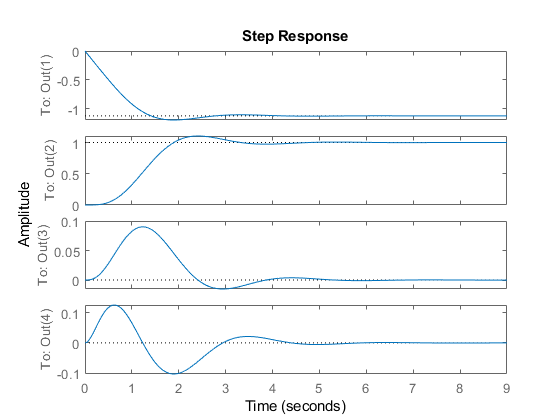


syscl = ss(Acl,Bcl,Ccl,Dcl);

step(syscl)


A = [0, 1,   0,  0;
     0, 0, -9.8, 0;
     0, 0,   0,  1;
     0, 0,   0,  0];
B = [0; 0; 0; 1];
C = [1 0 0 0];
D = [0];

Aw = [0 C;
      zeros([4,1]) A];
Bw = [D; B];
Cw = eye(5);
Dw = zeros([5,1]);

sysw = ss(Aw,Bw,Cw,Dw);
Q = diag([10, 0, 1, 1, 1]);
R = [1];
Kail = lqr(sysw,Q,R)

Kelev =    -3.1623   -5.4465   -4.6904   22.8613    6.8354


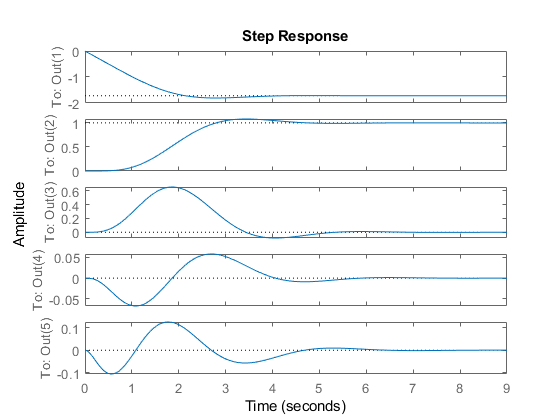


Acl = Aw-Bw*Kelev;
Bcl = [-1; 0; 0; 0; 0];
Ccl = eye(5);
Dcl = [0;0;0;0;0];

syscl = ss(Acl,Bcl,Ccl,Dcl);

step(syscl)